# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

% robot_name = 'kinovaGen3';
robot_name = "abbIrb120";
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

% endEffector = "EndEffector_Link"; %showdetails(robot) 首先查看body name 存不存在
endEffector = "tool0"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([0.4 0 0.2])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

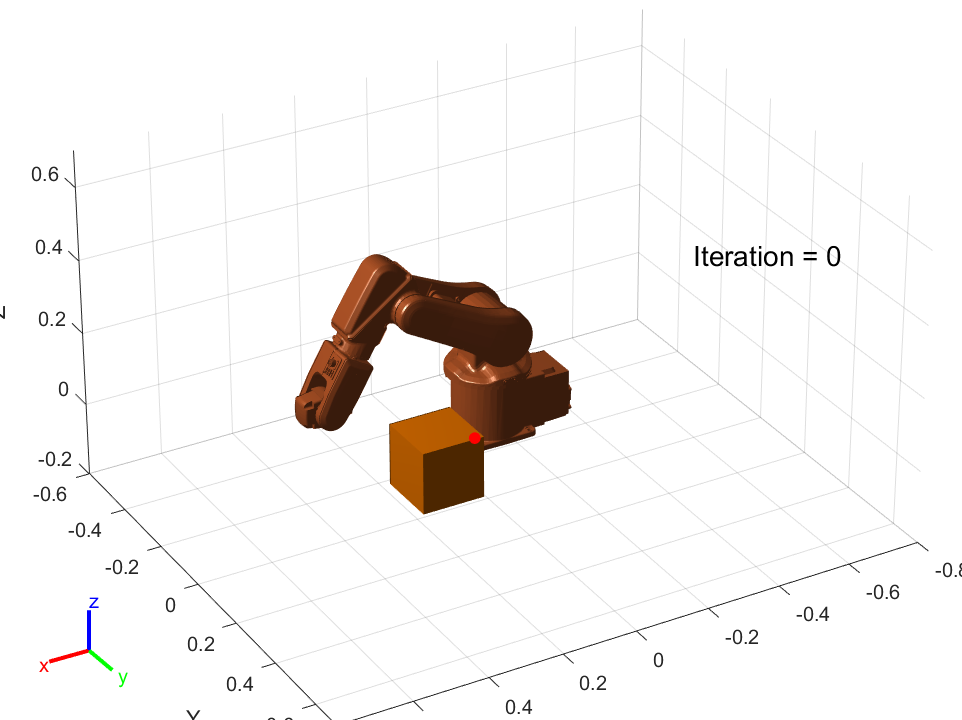

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

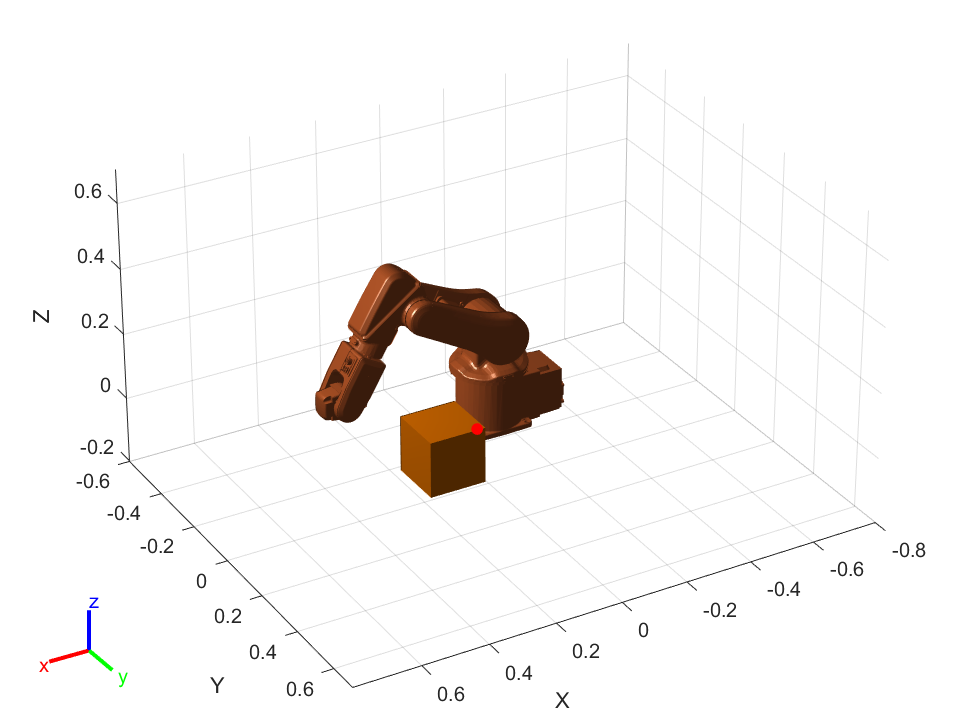

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Qtheta = 77.7409

RAR = 46.2370

Elapsed time is 1.412378 seconds.


Qtheta = 69.3733

RAR = 46.3621

Elapsed time is 1.418556 seconds.


Qtheta = 71.8382

RAR = 46.5023

Elapsed time is 1.428097 seconds.


Qtheta = 74.0400

RAR = 46.7806

Elapsed time is 1.105460 seconds.


Qtheta = 77.4988

RAR = 46.5980

Elapsed time is 1.697747 seconds.


Qtheta = 79.8112

RAR = 46.7820

Elapsed time is 1.579729 seconds.


Qtheta = 83.4713

RAR = 46.8774

Elapsed time is 1.112586 seconds.


Qtheta = 86.1052

RAR = 46.9880

Elapsed time is 0.997005 seconds.


Qtheta = 84.4940

RAR = 46.8421

Elapsed time is 1.009680 seconds.


Qtheta = 85.2656

RAR = 46.8103

Elapsed time is 1.620382 seconds.


Qtheta = 84.3706

RAR = 46.7509

Elapsed time is 1.134072 seconds.


Qtheta = 85.0202

RAR = 47.1993

Elapsed time is 1.754575 seconds.


Qtheta = 85.0205

RAR = 47.0361

Elapsed time is 1.138630 seconds.
STOMP Finished.


isTrajectoryInCollision = logical
   1


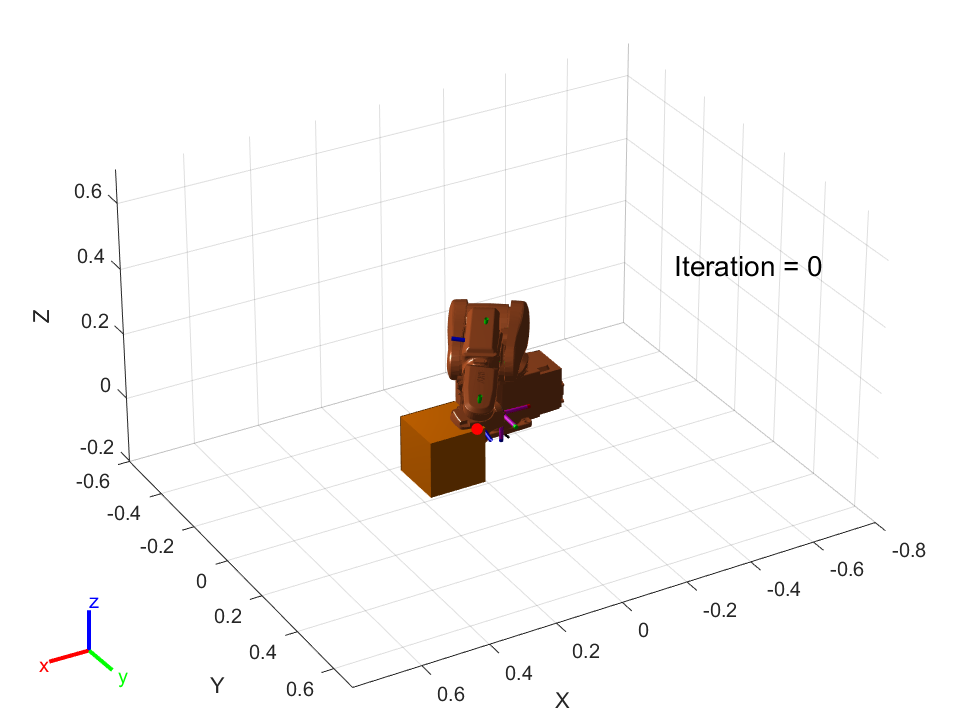

helperSTOMP;

[1K] M. alakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.